# Transformer Calculator

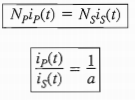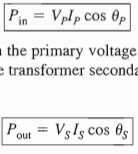

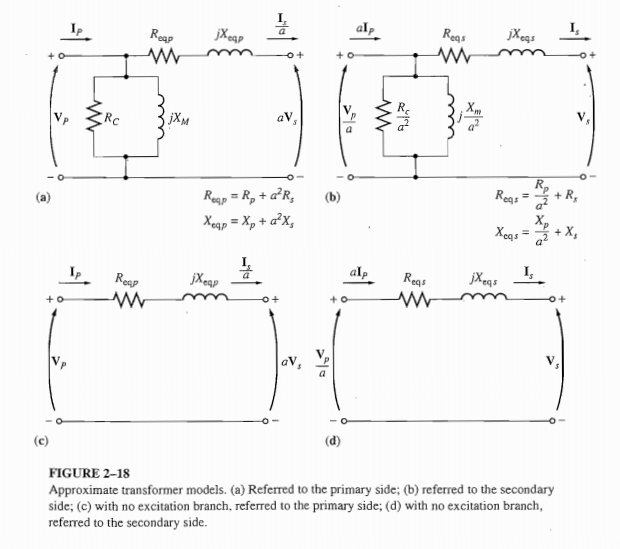

**Parameters**

Reqp=25;
 Reqs=0;
Xeqp=200;
 Xeqs=0;
Rcp=150000;
 Rcs=0;
Xmp=150000;
 Xms=0;
S=300000;
pf=0.8; % Geri (Açının işareti '-' olacak)
HVsidevoltage=34000; % DELTA
LVsidevoltage=4800/sqrt(3); % YILDIZ 
a=HVsidevoltage/LVsidevoltage 

a = 12.2687

Vs=4800/sqrt(3);
% Vp=27079;

**Calculations**

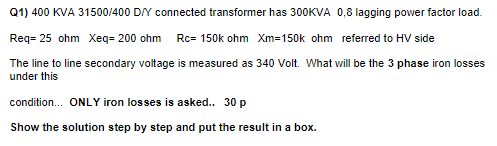

%---------------------- Vs verip, Vp isterse ---------------------------

Vp1=(Vs/sqrt(3))*a % YILDIZ OLDUĞU İÇİN VS sqrt(3)'E BÖLÜNDÜ.

Vp1 = 1.9630e+04


Ismag=S/(3*Vs)

Ismag = 36.0844

Isdeg=rad2deg(acos(pf));
Isdeg=-Isdeg % Geri olduğu için '-'

Isdeg = -36.8699

Is=(Ismag*cos(deg2rad(Isdeg)))+(Ismag*sin(deg2rad(Isdeg)))*j;

Ip=Is/a;
Ipmag=abs(Ip)

Ipmag = 2.9412

Ipdeg=rad2deg(angle(Ip))

Ipdeg = -36.8699


Vp=Vp1+(Reqp+Xeqp*j)*Ip;
Vpmag=abs(Vp)

Vpmag = 2.0046e+04

Vpdeg=rad2deg(angle(Vp))

Vpdeg = 1.2190


%-----------------------------------------------------------------------

%---------------------- Vp verip, Vs isterse ---------------------------

% Vs1=Vp/a
% 
% Ipmag=S/(3*Vp)
% Ipdeg=rad2deg(acos(pf))
% Ipdeg=-Ipdeg
% Ip=(Ipmag*cos(deg2rad(Ipdeg)))+(Ipmag*sin(deg2rad(Ipdeg)))*j;
% 
% Is=Ip*a;
% Ismag=abs(Is)
% Isdeg=rad2deg(angle(Is))
%
% Vs=(Vs1-(Reqs+Xeqs*j)*Is)*sqrt(3); % Yıldızda L-N den L-L ye dönüştürüldü
% Vsmag=abs(Vs)
% Vsdeg=rad2deg(angle(Vs))

%-----------------------------------------------------------------------


Piron1phase=(Vpmag^2)/Rcp

Piron1phase = 2.6790e+03

Piron3phase=3*Piron1phase

Piron3phase = 8.0370e+03


Pcopper1phase=Ipmag*Reqp

Pcopper1phase = 73.5294

Pcopper3phase=3*Pcopper1phase

Pcopper3phase = 220.5882